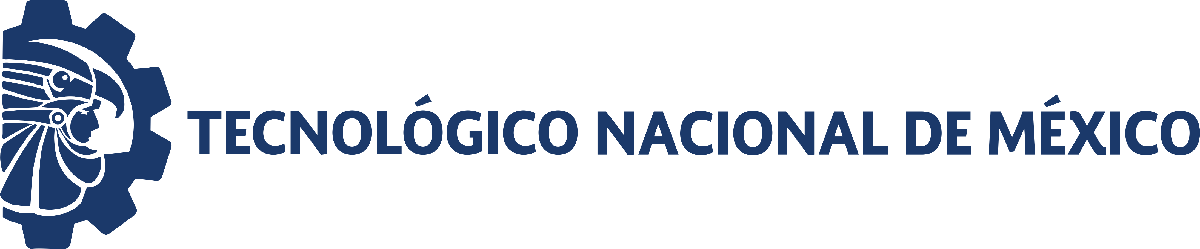                                 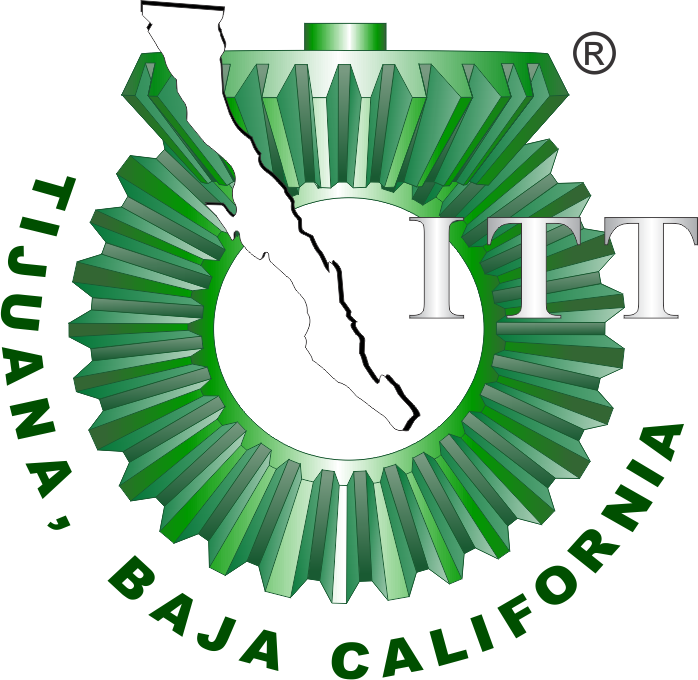

# Práctica tres: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

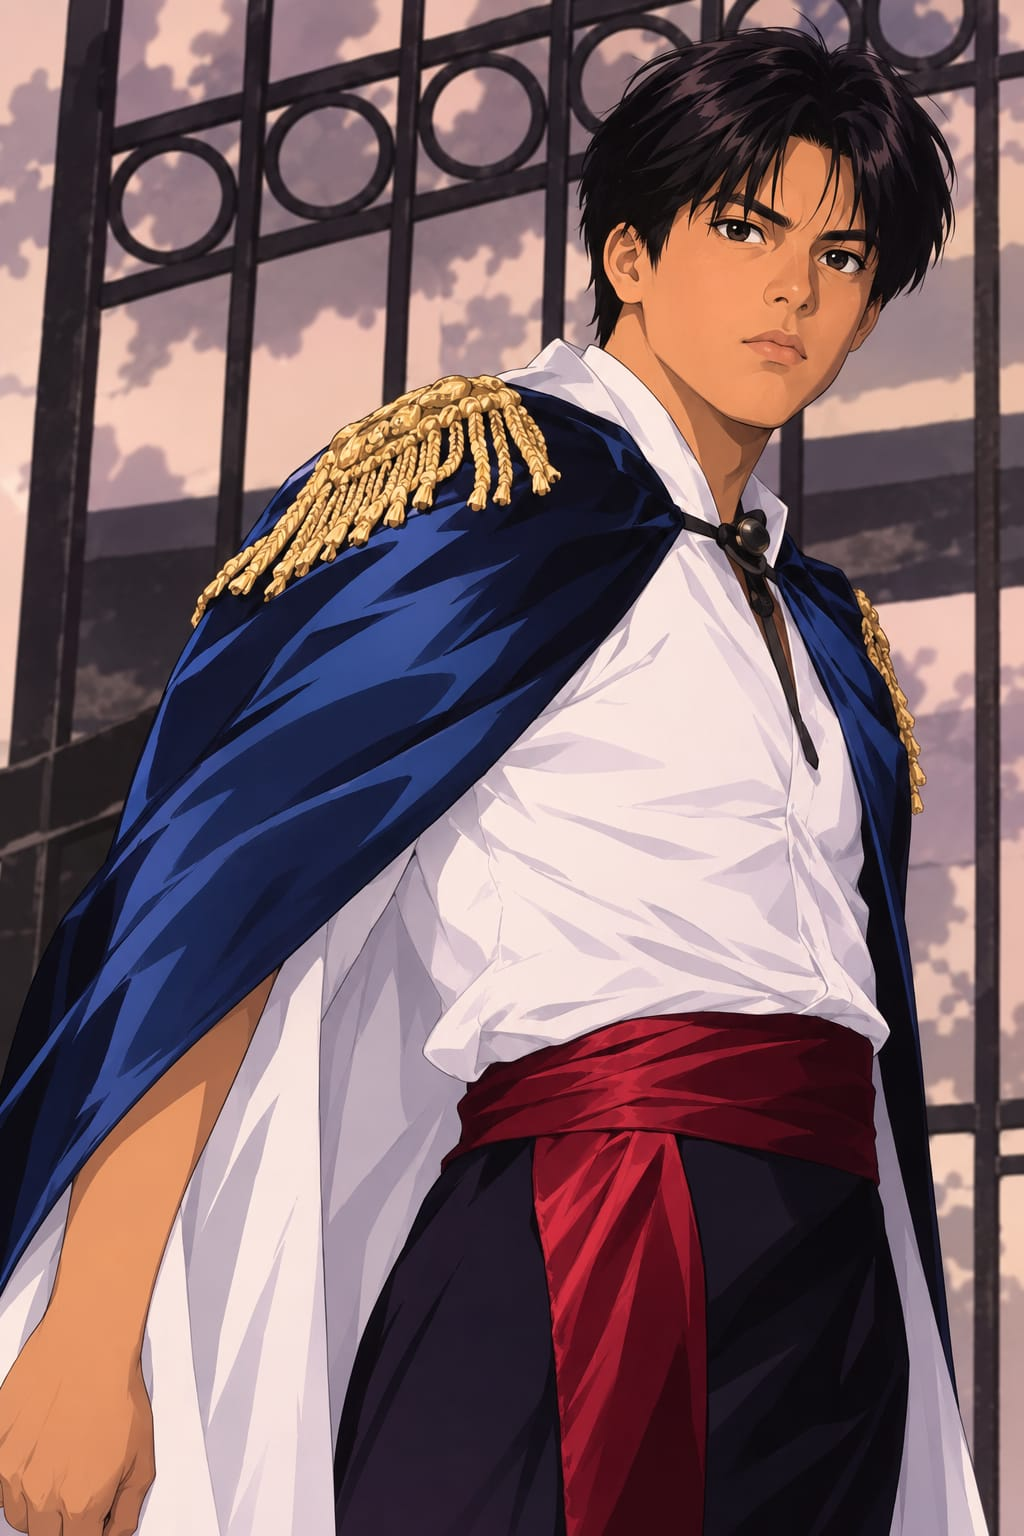

Nombre del alumno: **Emmanuel Cid Pacheco**

Número de control: **23212187**

Correo institucional: **l23212187@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim(file,parameters);

## Respuesta al impulso unitario

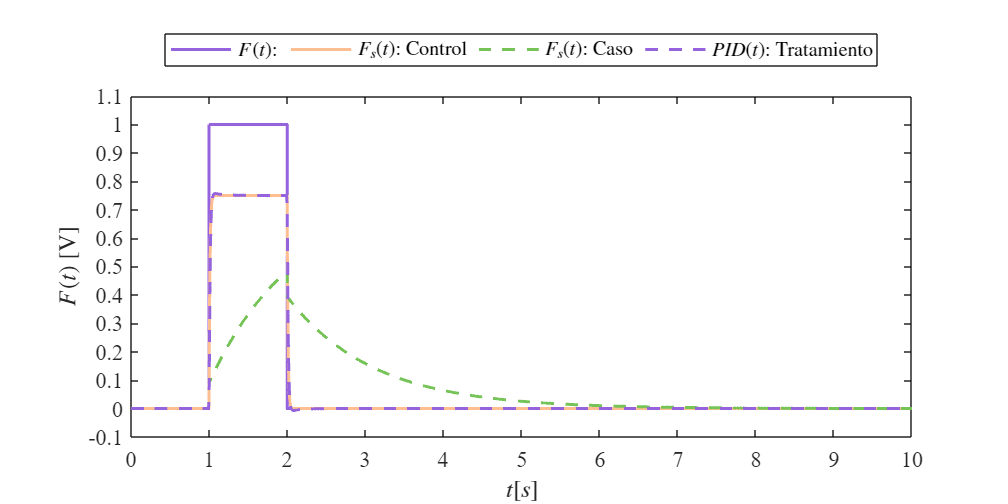

plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID)

## Función: Respuesta a las señales

function plotsignals(t, F, Fsx, Fsy, PID)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [149,100,221]/255;
    clr2 = [255,190,145]/255;
    clr3 = [118,196,87]/255;
    order = [clr1;clr2;clr3]; colororder(order)

plot(t,F,'-',t,Fsx,'-',t,Fsy,'--',t,PID,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1e3:length(t));
    L = legend('$F(t)$:','$F_{s}(t)$: Control', '$F_{s}(t)$: Caso', '$PID(t)$: Tratamiento');

set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    xlabel('$t[s]$','interpreter','latex')
    ylabel('$F(t)$ [V]','interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf, '_matlab.pdf','contenttype','vector')
end